clc; clear; close all;
run("active_suspension_ctrl_design.m");

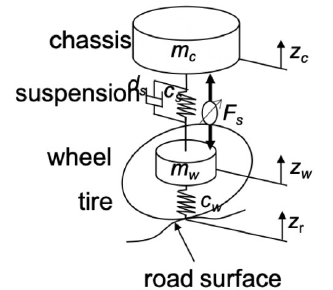

### Encuentre la matriz de observabilidad. ¿Es el sistema observable?

W = [C; C*A; C*A^2; C*A^3; C*A^4]

W = 	1.0e+10 *

   -0.0000         0    0.0000         0         0
    0.0000    0.0000   -0.0000   -0.0000    0.0000
         0   -0.0000         0    0.0000         0
   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.0001   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0113    0.0002   -0.0009   -0.0001   -0.0003
   -0.0018   -0.0000    0.0001    0.0000    0.0000
   -1.2332    0.0009    0.1091    0.0095    0.2627


if (rank(W) == 5)
    disp('Es observable completamente viendo el desplazamiento relativo del chasis a las ruedas y la aceleración en el chasis')
else
    disp('No es completamente observable')
end

Es observable completamente viendo el desplazamiento relativo del chasis a las ruedas y la aceleración en el chasis


### Verifique si el sistema es observable si solamente se mide la compresión del amortiguador.

C_aux = C(1,:);
W = [C_aux; C_aux*A; C_aux*A^2; C_aux*A^3; C_aux*A^4];
if (rank(W) == 5)
    disp('Es observable completamente viendo solo la compresión del amortiguador')
else
    disp('No es completamente observable')
end

Es observable completamente viendo solo la compresión del amortiguador


### Verifique si el sistema es observable si solamente se mide la posición de la rueda

C_aux = [0 1 0 0 0];
W = [C_aux; C_aux*A; C_aux*A^2; C_aux*A^3; C_aux*A^4];
if (rank(W) == 5)
    disp('Es observable completamente viendo solo la velocidad de las ruedas')
else
    disp('No es completamente observable')
end

Es observable completamente viendo solo la velocidad de las ruedas


### Luego de analizar los 2 escenarios posibles de observabilidad, ¿qué sensor o sensores de salida elegiría para este sistema?

Parece que es observble desde todos lados, así que usaría el sensor más práctico.

Me parece entonces que utilizaría un sensor que mida la compresión del amortiguador. Suena a que es sensillo de implementar.